P38    2.5.1 级数部分和

syms n x
s1 = symsum((-1)^(n+1)*x/(n*(n+2)),n,1,30)

$$s1 = \frac{495\,x}{1984}$$


syms n a k 
s2 = symsum((-1)^k*a*sin(k),k,0,n-1)

$$s2 = a\,\left(\frac{\left({\left(-1\right)}^{n}\,{\mathrm{e}}^{n\,\mathrm{i}}-1\right)\,\mathrm{i}}{2\,\left({\mathrm{e}}^{\mathrm{i}}+1\right)}+\frac{{\mathrm{e}}^{-n\,\mathrm{i}}\,{\mathrm{e}}^{\mathrm{i}}\,\left({\mathrm{e}}^{n\,\mathrm{i}}-{\left(-1\right)}^{n}\right)\,\mathrm{i}}{2\,\left({\mathrm{e}}^{\mathrm{i}}+1\right)}\right)$$


syms n
s3 = symsum(1/n^2,n,1,10)

$$s3 = \frac{1968329}{1270080}$$

P38    2.5.2 讨论级数敛散性

syms n
s1 = symsum(1/n^2,n,1,inf)

$$s1 = \frac{\pi^{2}}{6}$$


syms n
s2 = symsum(1/n,n,1,inf)

$$s2 = \infty$$


syms n a
s3 = symsum(a^n/n,n,1,inf)

$$s3 = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq a\\ -\log\left(1-a\right) & \text{ if }\left|a\right|\leq 1\wedge a\neq 1 \end{array}\right.$$

P39    2.5.3 讨论级数敛散性，并判断是绝对收敛还是条件收敛

syms n
s1 = symsum((-1)^n*n/3^(n-1),n,1,inf)

$$s1 = -\frac{9}{16}$$

s2 = symsum(n/3^(n-1),n,1,inf)    %绝对收敛

$$s2 = \frac{9}{4}$$


syms n
s3 = symsum((-1)^n/n,n,1,inf)

$$s3 = -\log\left(2\right)$$

s4 = symsum(1/n,n,1,inf)    %条件收敛

$$s4 = \infty$$

P40    2.5.4 调和级数实验——欧拉常数

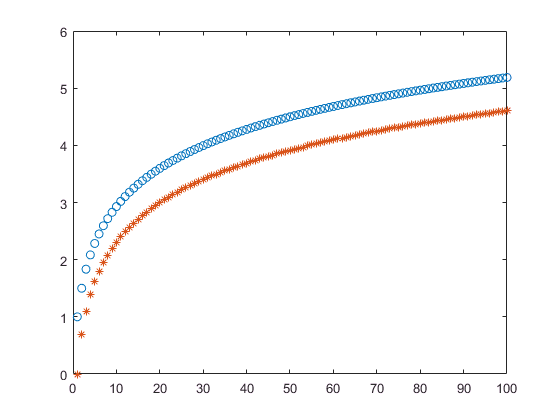

syms k 
for n = 1: 100
    x(n) = n ;
    y(n) = log(n);
    h(n) = double(symsum(1/k,k,1,n));
end
plot(x,h,'o',x,y,'*')


syms k
for i = 1 : 5
    h(i) = double(symsum(1/k,k,1,100^i));
    c(i) = h(i) - log(100^i);
end
format long;
c

c =    0.582207331651529   0.577265664068198   0.577216164901451   0.577215669901531   0.577215664951531



syms k n 
limit(symsum(1/k,k,1,n) - log(n),n,inf)

$$ans = \mathrm{eulergamma}$$